Import data and add column names to the datasets

df1 = readtable("data/data_haedong.csv");
df2 = readtable("data/data_trevor.csv");
df3 = readtable("data/data_con_collab.csv");

df1.Properties.VariableNames = ["Player","Action","Time"];
df2.Properties.VariableNames = ["Player","Action","Time"];

Bar graphs of activities for each player

freq_tbl1 = tabulate(df1.Action)

freq_tbl1 = 2×3 cell array
    {'Teleport Part'}    {[11]}    {[84.6154]}
    {'Spawn Pieces' }    {[ 2]}    {[15.3846]}


freq_tbl2 = tabulate(df2.Action)

freq_tbl2 = 2×3 cell array
    {'Teleport Part'}    {[26]}    {[74.2857]}
    {'Spawn Pieces' }    {[ 9]}    {[25.7143]}


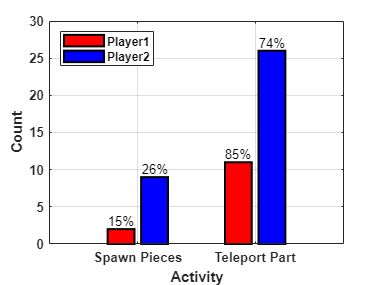


a = categorical(["Teleport Part","Spawn Pieces"]);
s = {'Player1','Player2'};
freq1 = transpose(cell2mat(freq_tbl1(:,2)));
freq2 = transpose(cell2mat(freq_tbl2(:,2)));
x = [freq1;freq2];

b = bar(a,x');
b(1).FaceColor = [1 0 0];
b(2).FaceColor = [0 0 1];
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = cell2mat(freq_tbl1(:,3))';
labels1 = round(labels1,0);
labels1 = strcat(string(labels1),"%");
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = cell2mat(freq_tbl2(:,3));
labels2 = round(labels2,0);
labels2 = strcat(string(labels2),"%");
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xlabel('Activity')
ylabel('Count')
set(b, {'DisplayName'},s');
set(b, {'linew'},{1.5});
set(gca,'FontWeight','bold')
legend('Location','northwest')
grid on

Evolvin graph

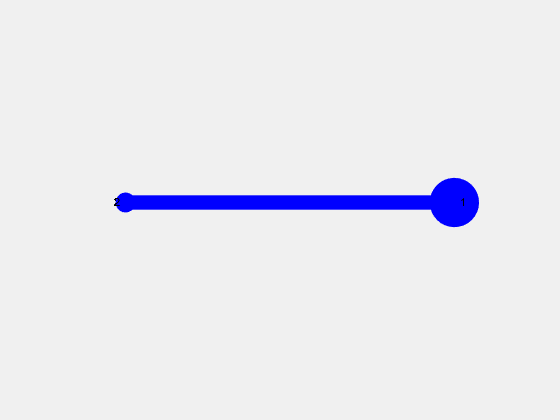

% default adjacency matrix
A = ones(2) - diag([1 1]);
G = graph(A);
[num_acts,~] = size(df3);
msize = [1,1];

figure
set(gcf,"Visible","on")
set(gca,"Visible","off")
for i=1:num_acts
    player = char(df3{i,"Player"});
    if isequal(player,'Trevor')
        msize(1) = msize(1)+1;
    else
        msize(2) = msize(2)+1;
    end
    hold on
    g = plot(G,"-b", "Layout","circle", "MarkerSize",msize, "LineWidth",df3{i,"Collaboration"});
    F(i) = getframe(gcf);
    drawnow
    hold off
end


video_obj = VideoWriter('collabo_graph.mp4', 'MPEG-4');
video_obj.FrameRate = 1;
open(video_obj);
writeVideo(video_obj, F);
close(video_obj);

Still shots of the collaboration graph

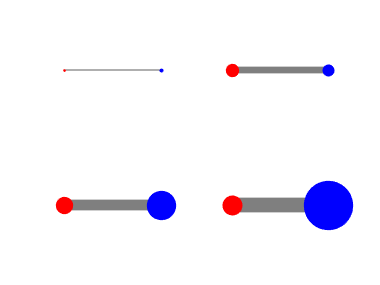

msize = [1,1];
figure('Color','w')
set(gca,'Visible','off')
for i=1:num_acts
    player = char(df3{i,"Player"});
    if isequal(player,'Trevor')
        msize(1) = msize(1)+1;
    else
        msize(2) = msize(2)+1;
    end
    
    if i==1
        subplot(2,2,1)
        g = plot(G,"-b", "Layout","circle", "MarkerSize",msize,...
            "LineWidth",df3{i,"Collaboration"},'NodeLabel',{});
        highlight(g,1,2,'EdgeColor','black')
        highlight(g,2,'NodeColor','red')
        set(gca,'Visible','off')
        title('Beginning')
    end
    
    if i==15
        subplot(2,2,2)
        g = plot(G,"-b", "Layout","circle", "MarkerSize",msize,...
            "LineWidth",df3{i,"Collaboration"},'NodeLabel',{});
        highlight(g,1,2,'EdgeColor','black')
        highlight(g,2,'NodeColor','red')
        set(gca,'Visible','off')
    end

    if i==31
        subplot(2,2,3)
        g = plot(G,"-b", "Layout","circle", "MarkerSize",msize,...
            "LineWidth",df3{i,"Collaboration"},'NodeLabel',{});
        highlight(g,1,2,'EdgeColor','black')
        highlight(g,2,'NodeColor','red')
        set(gca,'Visible','off')
    end

    if i==num_acts
        subplot(2,2,4)
        g = plot(G,"-b", "Layout","circle", "MarkerSize",msize,...
            "LineWidth",df3{i,"Collaboration"},'NodeLabel',{});
        highlight(g,1,2,'EdgeColor','black')
        highlight(g,2,'NodeColor','red')
        set(gca,'Visible','off')
    end
end

Markov chain modeling

% transition matrix
T = zeros(4);
x = string(df3{:,"Player"});
y = string(df3{:,"Activity"});


[num_rows,~] = size(df3);
for i=1:(num_rows-1)
    if (x(i)=="Trevor") && (x(i+1)=="Trevor")
        if (y(i)=="Teleport Part") && (y(i+1)=="Teleport Part")
            T(1,1) = T(1,1)+1;
        elseif (y(i)=="Teleport Part") && (y(i+1)=="Spawn Pieces")
            T(1,2) = T(1,2)+1;
        elseif (y(i)=="Spawn Pieces") && (y(i+1)=="Spawn Pieces")
            T(2,1) = T(2,1)+1;
        else
            T(2,2) = T(2,2)+1;
        end
    elseif (x(i)=="Trevor") && (x(i+1)=="Haedong")
        if (y(i)=="Teleport Part") && (y(i+1)=="Teleport Part")
            T(1,3) = T(1,3)+1;
        elseif (y(i)=="Teleport Part") && (y(i+1)=="Spawn Pieces")
            T(1,4) = T(1,4)+1;
        elseif (y(i)=="Spawn Pieces") && (y(i+1)=="Spawn Pieces")
            T(2,4) = T(2,4)+1;
        else
            T(2,3) = T(2,3)+1;
        end
    elseif (x(i)=="Haedong") && (x(i+1)=="Trevor")
        if (y(i)=="Teleport Part") && (y(i+1)=="Teleport Part")
            T(3,1) = T(3,1)+1;
        elseif (y(i)=="Teleport Part") && (y(i+1)=="Spawn Pieces")
            T(3,2) = T(3,2)+1;
        elseif (y(i)=="Spawn Pieces") && (y(i+1)=="Spawn Pieces")
            T(4,2) = T(4,2)+1;
        else
            T(4,1) = T(4,1)+1;
        end
    else
        if (y(i)=="Teleport Part") && (y(i+1)=="Teleport Part")
            T(3,3) = T(3,3)+1;
        elseif (y(i)=="Teleport Part") && (y(i+1)=="Spawn Pieces")
            T(3,4) = T(3,4)+1;
        elseif (y(i)=="Spawn Pieces") && (y(i+1)=="Spawn Pieces")
            T(4,4) = T(4,4)+1;
        else
            T(4,3) = T(4,3)+1;
        end
    end
end

for i=1:4
    T(i,:) = T(i,:)./sum(T(i,:));
end
disp(T)

    0.6154    0.0769    0.2692    0.0385
    0.7778    0.1111    0.1111         0
    0.7000         0    0.3000         0
    0.5000         0         0    0.5000




% steady-state probabilities
[V,D] = eig(T');
p = V(:,1)';
p = p./sum(p);
disp(p)

    0.6403    0.0554    0.2551    0.0493

